# H-inf + LPV

**(控制闭环系统、TNL观测器)**

clc;clear;
set(cstprefs.tbxprefs,'FrequencyUnits','Hz');

% 读取扰动数据、轨迹数据
load('disturb1124.mat');
% load('az_pre.mat');
load('az_pre_SLine.mat');
az_pre = az_pre - az_pre(1);
deltay = az_pre(2:end)-az_pre(1:end-1);

% 俯仰轴
vmax = 2;
amax = 0.5;
wsin = amax/vmax;
Asin = amax/(wsin^2);
Tsin = 2*pi/wsin;

% 系统参数
T_tol = 60;              % 仿真时长
Fs = 400;                % 仿真采样频率
Ts = 1/Fs;
T_simu = 0:1/Fs:T_tol;   % 仿真时间序列
k_tol = T_tol*Fs;        % 仿真总步数
% 电机、望远镜参数
L_dcm = 0.1;
R_dcm = 5;
C_dcm = 180/6*(30/pi);  % 反电动势系数 = 空载电压/最大空载转速
K_dcm = 200;        % 转矩系数 = 连续堵转转矩/电流
J_dcm = 110;
J_T = 70000;
fm = 0.1;         
fT = 1;      
kc = 7e5;

f_mode = sqrt(kc*(1/J_T+1/J_dcm))/2/pi;
disp(['望远镜的一阶谐振模态频率约为：', num2str(f_mode), ' Hz'])

望远镜的一阶谐振模态频率约为：12.7061 Hz



% 系统维数
nx = 5;     % 系统状态
ny = 1;     % 系统输出
nd = 1;     % 扰动输入
nu = 1;     % 控制输入
n1w = nx;   % 过程噪声
n2w = ny;   % 测量噪声
nXI = 1;    % /Xi
nr = 5;     % 预见序列长度
n_noise = nx+ny;                % 原系统总噪声（过程噪声+测量噪声）
nwa = n_noise + nd;             % 扩张扰动系统总噪声
nH = 2*nwa+nx+nd;           % 观测误差系统扰动（\varpi）
nw = nwa*2 + ny;              % 控制闭环系统扰动（ω_ξ）

nG = 2*nx + nd + ny + nr;     % 控制器李雅普诺夫函数矩阵

k_current = 1e2;
k_disturb = 1e7;
k_deg2rad = pi/180;

% 缩放系统量纲，电流i单位为1/k_current A，望远镜/电机转角单位为deg，扰动单位为1/k_disturb N·m
%               i                               wm              theta_m                   wt        theta_T
Asys0 = [-R_dcm/L_dcm                -C_dcm/L_dcm/k_current      0                       0           0;
        K_dcm/J_dcm*k_current       -fm/J_dcm                   -kc/J_dcm*k_deg2rad     0           kc/J_dcm*k_deg2rad;
        0                           1/k_deg2rad                 0                       0           0;
        0                           0                           kc/J_T*k_deg2rad      -fT/J_T       -kc/J_T*k_deg2rad;
        0                           0                           0                       1/k_deg2rad           0     ];
Bsys = [1/L_dcm/k_current*180/5 0 0 0 0]';
Csys = [0 0 0 0 1];                        % 测量/控制输出为 望远镜转角（deg）
Dsys = zeros(ny,nu);
Esys = [0 0 0 1/J_T*k_disturb 0]';         % 实际扰动输入

Ad = expm(Ts.*Asys0);
fun = @(x) expm(Asys0.*x);
q = integral(fun, 0, Ts, 'ArrayValued',true);
Bd = q*Bsys;
Ed = q*Esys;
Cd = Csys;
D1d = [eye(nx) zeros(nx,ny)];
D2d = [zeros(ny,nx) eye(ny)];

% Aa = [Ad Ed;zeros(nd,nx) eye(nd)];
Ba = [Bd; 0];
Ca = [Cd 0];
D1a = [D1d zeros(nx,nd);zeros(nd,nx+nd) 1]*1e-3;
D2a = [D2d zeros(nd)]*1e-3;

J_T = 68843*1.05;
Asys = [-R_dcm/L_dcm                -C_dcm/L_dcm/k_current      0                       0           0;
        K_dcm/J_dcm*k_current       -fm/J_dcm                   -kc/J_dcm*k_deg2rad     0           kc/J_dcm*k_deg2rad;
        0                           1/k_deg2rad                 0                       0           0;
        0                           0                           kc/J_T*k_deg2rad      -fT/J_T       -kc/J_T*k_deg2rad;
        0                           0                           0                       1/k_deg2rad           0     ];
Ad1 = expm(Ts.*Asys);
Aa1 = [Ad1 Ed;zeros(nd,nx) eye(nd)];

J_T = 68843*0.95;
Asys = [-R_dcm/L_dcm                -C_dcm/L_dcm/k_current      0                       0           0;
        K_dcm/J_dcm*k_current       -fm/J_dcm                   -kc/J_dcm*k_deg2rad     0           kc/J_dcm*k_deg2rad;
        0                           1/k_deg2rad                 0                       0           0;
        0                           0                           kc/J_T*k_deg2rad      -fT/J_T       -kc/J_T*k_deg2rad;
        0                           0                           0                       1/k_deg2rad           0     ];
Ad2 = expm(Ts.*Asys);
Aa2 = [Ad2 Ed;zeros(nd,nx) eye(nd)];

% fun = @(x) expm(Asys.*x);
% q = integral(fun, 0, Ts, 'ArrayValued',true);
% Bd = q*Bsys;
% Ed = q*Esys;

% Ad = Ts.*Asys + eye(nx);
% Bd = Ts*Bsys;
% Ed = Ts*Esys;
deltaAd = zeros(nx,nx);
K_Ad = 0.1;
deltaAd(4,3) = K_Ad*Asys0(4,3)*Ts;
deltaAd(4,4) = K_Ad*Asys0(4,4)*Ts;
deltaAd(4,5) = K_Ad*Asys0(4,5)*Ts;

IC = [eye(nx+nd);Ca];
IC_pinv = pinv(IC,1e-4);
Y = [0 0 1 0 0 0 0]%ones(1,7);   %任意矩阵[0 0 0 0 0 0 1]%

Y =      0     0     1     0     0     0     0


TN = IC_pinv + Y*(eye(nx+ny+nd)-IC*IC_pinv);
T = TN(:,1:nx+nd)

T =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    0.5000         0
         0         0         0         0         0    1.0000


N = TN(:,nx+nd+1:end);
TNC = T+N*Ca;

if rank(TNC)==size(T,1)
    disp('判断：T+NC等于单位阵');
else
    disp('判断：T+NC不为单位阵');
end

判断：T+NC等于单位阵


### 观测器LMI求解

yalmip('clear')

P = sdpvar(nx+nd,nx+nd,'symmetric');
Q = sdpvar(nx+nd,nx+nd,'full');
R1 = sdpvar(nx+nd,ny,'full');
R2 = sdpvar(nx+nd,ny,'full');
EPSILON = sdpvar(1,1);
GAMMA2 = sdpvar(1,1);

Uori = zeros(nx+nd);
k_UW = 1e-2;

Uori(4,3) = Asys0(4,3)*K_Ad*Ts/k_UW;
Uori(4,4) = Asys0(4,4)*K_Ad*Ts/k_UW;
Uori(4,5) = Asys0(4,5)*K_Ad*Ts/k_UW;
Wori = diag([0 0 1 1 1 0])*k_UW;

Uori*Wori

ans = 1.0e-04 *

         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0    0.4363   -0.0000   -0.4363         0
         0         0         0         0         0         0
         0         0         0         0         0         0



U = Uori;
W = Wori;
WW = [zeros(nx+nd,nH-nx-nd) W]'*[zeros(nx+nd,nH-nx-nd) W];

M1 = [-P+eye(nx+nd)          zeros(nx+nd,nH)                     (Q*T*Aa1-R1*Ca)'                                zeros(nx+nd,nx+nd);
    zeros(nH,nx+nd)   -GAMMA2*eye(nH)+EPSILON*WW         [Q*T*D1a-R1*D2a -Q*N*D2a zeros(nx+nd,nx+nd)]' zeros(nH,nx+nd);
    Q*T*Aa1-R1*Ca        Q*T*D1a-R1*D2a -Q*N*D2a zeros(nx+nd)   P-Q-Q'                                      Q*T*U;
    zeros(nx+nd,nx+nd+nH)  (Q*T*U)'    -EPSILON*eye(nx+nd)]; 
M2 = P-eye(nx+nd);
M3 = GAMMA2*eye(nH)-EPSILON*WW;
M4 = [-P+eye(nx+nd)          zeros(nx+nd,nH)                     (Q*T*Aa2-R2*Ca)'                                zeros(nx+nd,nx+nd);
    zeros(nH,nx+nd)   -GAMMA2*eye(nH)+EPSILON*WW         [Q*T*D1a-R2*D2a -Q*N*D2a zeros(nx+nd,nx+nd)]' zeros(nH,nx+nd);
    Q*T*Aa2-R2*Ca        Q*T*D1a-R2*D2a -Q*N*D2a zeros(nx+nd)   P-Q-Q'                                      Q*T*U;
    zeros(nx+nd,nx+nd+nH)  (Q*T*U)'    -EPSILON*eye(nx+nd)]; 
LMIs = [M1<=0,M2>=0,M3>=0,M4<=0,EPSILON>=0, GAMMA2>=0];

opts = sdpsettings('solver','mosek');
opts.showprogress = 1;
diagno = optimize(LMIs,GAMMA2,opts)

+ Solver chosen : MOSEK-SDP
+ Processing objective function
+ Processing constraints
+ Calling Mosek

MOSEK Version 11.0.29 (Build date: 2025-9-24 22:02:28)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 71              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 2               
  Matrix variables       : 4 (scalarized: 1713)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  

diagno = 包含以下字段的 struct :
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2668659 (R2023b) Update 9'
       yalmiptime: 0.5192
       solvertime: 0.0398
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


if diagno.problem == 0
    disp('求解成功');
else
    disp(['求解出错！错误代码：', num2str(diagno.problem)]);
end

求解成功



check(LMIs)

 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|        4.3805e-09|      1.6832e-11|
|   #2|        Matrix inequality|           0.67207|      3.2114e-11|
|   #3|        Matrix inequality|        0.00095254|      7.1002e-07|
|   #4|        Matrix inequality|        5.8972e-09|      1.6654e-11|
|   #5|   Elementwise inequality|           17.4395|     -8.5545e-11|
|   #6|   Elementwise inequality|         0.0026965|      7.0979e-07|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negativ


P =double(P);
Q = double(Q);
R1 = double(R1);
R2 = double(R2);
L1 = Q\R1

L1 =    -0.0904
    0.4076
    0.2462
    3.5586
    0.7413
    0.9864


L2 = Q\R2

L2 =    -0.0902
    0.4074
    0.2464
    3.5579
    0.7412
    0.9864


EPSILON = double(EPSILON);
GAMMA2 = double(GAMMA2)

GAMMA2 = 0.0027


disp('观测误差系统闭环极点：');

观测误差系统闭环极点：


eig_obser1 = abs(eig(Aa1-L1*Ca))

eig_obser1 =     0.9129
    0.9129
    0.9741
    0.9741
    0.9300
    0.8918


if max(abs(eig(Aa1-L1*Ca)))>1
   disp('注意！系统不稳定！');
elseif max(abs(eig(Aa1-L1*Ca)))== 1
    disp('系统临界稳定');
else 
    disp('系统稳定');
end

系统稳定



eig_obser2 = abs(eig(Aa2-L2*Ca))

eig_obser2 =     0.9129
    0.9129
    0.9741
    0.9741
    0.9300
    0.8918


if max(abs(eig(Aa2-L2*Ca)))>1
   disp('注意！系统不稳定！');
elseif max(abs(eig(Aa2-L2*Ca)))== 1
    disp('系统临界稳定');
else 
    disp('系统稳定');
end

系统稳定


选取增广系统状态量$\xi \left(k\right)=\left\lbrack \begin{array}{c}
\Delta x_d \left(k\right)\\
e_c \left(k\right)\\
r^* \left(k\right)\\
\Delta e_o \left(k\right)
\end{array}\right\rbrack$

误差动态：


$$\xi \left(k+1\right)=\left(A_{\xi } +\Delta A_{\xi } \right)\xi \left(k\right)+B_{\xi } \Delta u\left(k\right)+D_{\xi } w_{\xi } \left(k\right)$$


$A_{\xi } =\left\lbrack \begin{array}{cccc}
A_d  &  &  & \\
-C_d  & I & C_r  & \\
 &  & A_r  & \\
 &  &  & A_a {-\textrm{LC}}_a 
\end{array}\right\rbrack$,$\Delta A_{\xi } =\left\lbrack \begin{array}{cccc}
{\Delta A}_d  &  &  & \\
 &  &  & \\
 &  &  & \\
\left\lbrack \begin{array}{c}
{\Delta A}_a \\
0
\end{array}\right\rbrack  &  &  & 
\end{array}\right\rbrack$,


$$B_{\xi } =\left\lbrack \begin{array}{c}
B_d \\
\\
\\

\end{array}\right\rbrack ,D_{\xi } =\left\lbrack \begin{array}{c}
\\
\\
D_r \\

\end{array}\right\rbrack$$


设计$\Delta u\left(k\right)=-M_x {\hat{x} }_d -M_d \hat{d} \left(k\right)-M_r r^* \left(k\right)-M_e e_c \left(k\right)$,


$$M_d =B_a^{\dagger} \left\lbrack \begin{array}{c}
E_d \\
0
\end{array}\right\rbrack$$


闭环误差动态：


$$\xi \left(k+1\right)=\left(A_{\textrm{cl}} +\Delta A_{\xi } \right)\xi \left(k\right)+D_{\xi } w_{\xi } \left(k\right)$$



$$\begin{array}{l}
A_{\textrm{cl}} =\left\lbrack \begin{array}{cccc}
A_d  &  &  & \\
-C_d  & I & C_r  & \\
 &  & A_r  & \\
 &  &  & A_a {-\textrm{LC}}_a 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
B_d \\
\\
\\

\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
M_x  & M_e  & M_r  & -\left\lbrack \begin{array}{cc}
M_x  & B_d^{\dagger} E_d 
\end{array}\right\rbrack 
\end{array}\right\rbrack \\
=\left\lbrack \begin{array}{cccc}
A_d  &  &  & \\
-C_d  & I & C_r  & \\
 &  & A_r  & \\
 &  &  & A_a {-\textrm{LC}}_a 
\end{array}\right\rbrack -\left\lbrack \begin{array}{cccc}
B_d M_x  & B_d M_e  & B_d M_r  & \left\lbrack \begin{array}{cc}
{-B}_d M_x  & E_d 
\end{array}\right\rbrack \\
 &  &  & \\
 &  &  & \\
 &  &  & 
\end{array}\right\rbrack 
\end{array}$$


% 预见序列系统 系统矩阵
Ar = [zeros(nr-1,ny) eye(nr-1); zeros(ny,nr)];
Cr = zeros(ny,nr);
Cr(1:ny,1:ny) = eye(ny);
Dr = zeros(nr,ny);
Dr((end-ny+1):end,:) = eye(ny);



$$A_{\xi } =\left\lbrack \begin{array}{cccc}
A_d  &  &  & \\
-C_d  & I & C_r  & \\
 &  & A_r  & \\
 &  &  & A_a {-\textrm{LC}}_a 
\end{array}\right\rbrack$$


% Axi = zeros(nG,nG);
% Axi(1:nx,1:nx) = Ad;
% Axi(nx+ny,1:nx) = -Cd;
% Axi(nx+ny,nx+1:nx+ny) = eye(ny);
% Axi(nx+ny,(ny+nx+1):(nG-nx-nd)) = Cr;
% Axi((ny+nx+1):(ny+nx+nr),(ny+nx+1):(ny+nx+nr)) = Ar;
% Axi((nG-nx-nd+1):end,(nG-nx-nd+1):end) = Aa-L*Ca;
% Axi;


Axi1 = zeros(nG,nG);
Axi1(1:nx,1:nx) = Ad1;
Axi1(nx+ny,1:nx) = -Cd;
Axi1(nx+ny,nx+1:nx+ny) = eye(ny);
Axi1(nx+ny,(ny+nx+1):(nG-nx-nd)) = Cr;
Axi1((ny+nx+1):(ny+nx+nr),(ny+nx+1):(ny+nx+nr)) = Ar;
Axi1((nG-nx-nd+1):end,(nG-nx-nd+1):end) = Aa1-L1*Ca;
Axi1;

Axi2 = zeros(nG,nG);
Axi2(1:nx,1:nx) = Ad2;
Axi2(nx+ny,1:nx) = -Cd;
Axi2(nx+ny,nx+1:nx+ny) = eye(ny);
Axi2(nx+ny,(ny+nx+1):(nG-nx-nd)) = Cr;
Axi2((ny+nx+1):(ny+nx+nr),(ny+nx+1):(ny+nx+nr)) = Ar;
Axi2((nG-nx-nd+1):end,(nG-nx-nd+1):end) = Aa2-L2*Ca;
Axi2;

% eig_Axi = abs(eig(Axi));
% eig_Axi11 = abs(eig(Axi(1:ny+nx+nr,1:ny+nx+nr)));


$$B_{\xi } =\left\lbrack \begin{array}{c}
B_d \\
\\
\\

\end{array}\right\rbrack$$


Bxi = [Bd; zeros(ny,nu);  zeros(nr+nx+nd,nu)];

% Cxi = [eye(ny) zeros(1,nG-ny)];


$$D_{\xi } =\left\lbrack \begin{array}{ccc}
\left\lbrack \begin{array}{cc}
D_{1d}  & 
\end{array}\right\rbrack  &  & \\
-D_{2a}  &  & \\
 &  & D_r \\
H_1  & H_2  & 
\end{array}\right\rbrack$$


% Dxi = zeros(nG,2*(nx+ny+nd)+ny);
% Dxi(1:nx,1:(nx+ny)) = D1a(1:nx,1:(nx+ny));
% Dxi((nx+1):(nx+ny),1:(nx+ny+nd)) = D2a;
% Dxi((ny+nx+1):(end-nx-nd),end) = Dr;
% 
% H1 = T*D1a - L*D2a;
% H2 = -N*D2a;
% Dxi((nx+ny+nr+1):end,1:end-ny) = [H1 H2];
% 
% Dxi;

Dxi1 = zeros(nG,2*(nx+ny+nd)+ny);
Dxi1(1:nx,1:(nx+ny)) = D1a(1:nx,1:(nx+ny));
Dxi1((nx+1):(nx+ny),1:(nx+ny+nd)) = D2a;
Dxi1((ny+nx+1):(end-nx-nd),end) = Dr;

H1_1 = T*D1a - L1*D2a;
H2_1 = -N*D2a;
Dxi1((nx+ny+nr+1):end,1:end-ny) = [H1_1 H2_1];

Dxi1;

Dxi2 = zeros(nG,2*(nx+ny+nd)+ny);
Dxi2(1:nx,1:(nx+ny)) = D1a(1:nx,1:(nx+ny));
Dxi2((nx+1):(nx+ny),1:(nx+ny+nd)) = D2a;
Dxi2((ny+nx+1):(end-nx-nd),end) = Dr;

H1_2 = T*D1a - L2*D2a;
H2_2 = -N*D2a;
Dxi2((nx+ny+nr+1):end,1:end-ny) = [H1_2 H2_2];

Dxi2;

H无穷优化

H无穷性能函数：$J=\sum_{k=0}^{\infty } e_c^T \left(k\right)R_1 e_c \left(k\right)+\Delta u^T R_2 \Delta u\left(k\right)=\sum_{k=0}^{\infty } {z\left(k\right)}^T z\left(k\right)$

误差动态：


$$\left\lbrace \begin{array}{l}
\xi \left(k+1\right)=\left(A_{\xi } +\Delta A_{\xi } \right)\xi \left(k\right)+B_{\xi } \Delta u\left(k\right)+D_{\xi } w_{\xi } \\
z\left(k\right)=A_z \xi \left(k\right)+B_z \Delta u\left(k\right)
\end{array}\right.$$



$$A_z =\left\lbrack \begin{array}{c}
\sqrt{R_1 }C_{\xi } \\
0
\end{array}\right\rbrack ,B_z =\left\lbrack \begin{array}{c}
0\\
\sqrt{R_2 }
\end{array}\right\rbrack$$


LMI: $\Delta V_c \left(k\right)+{z\left(k\right)}^T z\left(k\right)-\gamma^2 {w_{\xi } \left(k\right)}^T w_{\xi } \left(k\right)\prec 0$

Cxi = [zeros(ny,nx) eye(ny) zeros(ny,nr+nx+nd)];
% R1 = 480;
% R2 = 0.0001;

R1 = 1.8e3;
R2 = 1e-5;

Az = [R1*Cxi(:,1:nx+ny+nr); zeros(nu,nx+ny+nr)];
Bz = [zeros(ny,nu);R2];

yalmip('clear')

Almi1 = Axi1(1:nx+ny+nr,1:nx+ny+nr);
Almi2 = Axi2(1:nx+ny+nr,1:nx+ny+nr);
Blmi = Bxi(1:nx+ny+nr,:);
Clmi = Cxi(:,1:nx+ny+nr);
Dlmi1 = Dxi1(1:nx+ny+nr,:)*1e-3;
Dlmi2 = Dxi2(1:nx+ny+nr,:)*1e-3;

Ulmi = [Uori(1:nx,1:nx);zeros(ny+nr,nx)];
Wlmi = [Wori(1:nx,1:nx) zeros(nx,ny+nr)];

GAMMA2c = sdpvar(ny,ny,'full');
KAPPAinv = sdpvar(1,1,'full');
Ginv = sdpvar(nx+ny+nr,nx+ny+nr,'symmetric');
MGinv1 = sdpvar(nu,nx+ny+nr,'full');
MGinv2 = sdpvar(nu,nx+ny+nr,'full');
Mc1 = [-Ginv                     zeros(nx+ny+nr,nw)     (Almi1*Ginv - Blmi*MGinv1)'   zeros(nx+ny+nr,nx)  (Wlmi*Ginv)'        (Az*Ginv - Bz*MGinv1)';
       zeros(nw,nx+ny+nr)        -GAMMA2c*eye(nw)       Dlmi1'                       zeros(nw,nx)        zeros(nw,nx)        zeros(nw,ny+nu);
       Almi1*Ginv - Blmi*MGinv1    Dlmi1                   -Ginv                       KAPPAinv*Ulmi       zeros(nx+ny+nr,nx)  zeros(nx+ny+nr,ny+nu);
       zeros(nx,nx+ny+nr)        zeros(nx,nw)           KAPPAinv*Ulmi'              -KAPPAinv*eye(nx)   zeros(nx,nx)        zeros(nx,ny+nu);
       Wlmi*Ginv                 zeros(nx,nw)           zeros(nx,nx+ny+nr)          zeros(nx,nx)        -KAPPAinv*eye(nx)   zeros(nx,ny+nu);
       Az*Ginv - Bz*MGinv1        zeros(ny+nu,nw)        zeros(ny+nu,nx+ny+nr)       zeros(ny+nu,nx)     zeros(ny+nu,nx)     -eye(ny+nu)];
Mc2 = [-Ginv                     zeros(nx+ny+nr,nw)     (Almi2*Ginv - Blmi*MGinv2)'   zeros(nx+ny+nr,nx)  (Wlmi*Ginv)'        (Az*Ginv - Bz*MGinv2)';
       zeros(nw,nx+ny+nr)        -GAMMA2c*eye(nw)       Dlmi2'                       zeros(nw,nx)        zeros(nw,nx)        zeros(nw,ny+nu);
       Almi2*Ginv - Blmi*MGinv2    Dlmi2                  -Ginv                       KAPPAinv*Ulmi       zeros(nx+ny+nr,nx)  zeros(nx+ny+nr,ny+nu);
       zeros(nx,nx+ny+nr)        zeros(nx,nw)           KAPPAinv*Ulmi'              -KAPPAinv*eye(nx)   zeros(nx,nx)        zeros(nx,ny+nu);
       Wlmi*Ginv                 zeros(nx,nw)           zeros(nx,nx+ny+nr)          zeros(nx,nx)        -KAPPAinv*eye(nx)   zeros(nx,ny+nu);
       Az*Ginv - Bz*MGinv2        zeros(ny+nu,nw)        zeros(ny+nu,nx+ny+nr)       zeros(ny+nu,nx)     zeros(ny+nu,nx)     -eye(ny+nu)];

LMIcs = [Mc1<= -3e-9*eye(49), Mc2<= -3e-9*eye(49), Ginv>=0, GAMMA2c>=0, KAPPAinv>=0];
% -1e-9*eye(49)
opts =  sdpsettings('solver','mosek');
diagno = optimize(LMIcs,GAMMA2c,opts)

MOSEK Version 11.0.29 (Build date: 2025-9-24 22:02:28)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 90              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 2               
  Matrix variables       : 3 (scalarized: 2516)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

diagno = 包含以下字段的 struct :
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2668659 (R2023b) Update 9'
       yalmiptime: 0.1091
       solvertime: 0.1869
             info: 'Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (MOSEK-SDP)'
          problem: 4


check(LMIcs);

 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|        -2.451e-09|        1.03e-07|
|   #2|        Matrix inequality|       -2.3945e-09|      1.0343e-07|
|   #3|        Matrix inequality|        5.9476e-09|       1.036e-07|
|   #4|   Elementwise inequality|            5.0397|        0.013064|
|   #5|   Elementwise inequality|         0.0074168|          8.8812|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negative residuals (i.e. infeasibilities)                |
| https://yalmip.g

KAPPAinv = value(KAPPAinv)

KAPPAinv = 0.0074

Mc1 = value(Mc1);
MGinv1 = value(MGinv1);
MGinv2 = value(MGinv2);
Ginv = value(Ginv);
GAMMA2c = value(GAMMA2c)

GAMMA2c = 5.0397

Kc1 = MGinv1/Ginv;
Kc2 = MGinv2/Ginv;
Kc_all1 = [Kc1 -Kc1(1:nx) pinv(Bd)*Ed];
Kc_all2 = [Kc2 -Kc2(1:nx) pinv(Bd)*Ed];
abs(eig(Axi1-Bxi*Kc_all1))

ans =     0.3057
    0.3057
    0.5520
    0.5520
    0.1323
    0.2529
    0.9129
    0.9129
    0.9741
    0.9741


if max(abs(eig(Axi1-Bxi*Kc_all1)))>= 1
    disp('系统不稳定');
end

Aa = [Ad Ed;zeros(nd,nx) eye(nd)];
L = L1;
Kc = Kc1;

lp_f_MeasNoise = 8*2*pi;
% lptf_MeasNoise = tf(1,[1/(lp_f_MeasNoise) 1]);
lptf_MeasNoise = tf(1,[1/(lp_f_MeasNoise^2) 2/lp_f_MeasNoise 1]);
lptf_MeasNoise_d = c2d(lptf_MeasNoise,Ts);
[z_MN,p_MN,k_MN] = zpkdata(lptf_MeasNoise_d,'vector');

wc = 5*2*pi;
wo_ADRC = 150*2*pi;
beta = exp(-wo_ADRC*Ts);
b0 = 9;
A_esos = [1 Ts Ts^2/2;0 1 Ts; 0 0 1];
B_esos = [b0*Ts^2/2; b0*Ts; 0];
Lc_eso = [1-beta^3; (1-beta)^2*(1+beta)*3/2/Ts;(1-beta)^3/(Ts^2)];
Lp_eso = A_esos*Lc_eso;
C_esos = [1 0 0];
D_esos = 0;

A_eso = A_esos-Lp_eso*C_esos;
B_eso = [B_esos,Lp_eso];
C_eso = eye(3);
D_eso = zeros(3,2);


plant = ss(Ad,Bd,Cd,[],Ts);
opt = pidtuneOptions('DesignFocus','reference-tracking');
pid_p = pidtune(plant,'PIDF',4*2*pi,opt);
[z_pid,p_pid,k_pid] = zpkdata(pid_p,'vector');

load('ctrl1122.mat');
[z_of,p_of,k_of] = zpkdata(C4,'vector');

rms(out.PID)

ans = 51.8111

rms(out.OF)

ans = 8.1418

rms(out.ADRC)

ans = 8.8437

rms(out.PROPOSE)

ans = 0.3251

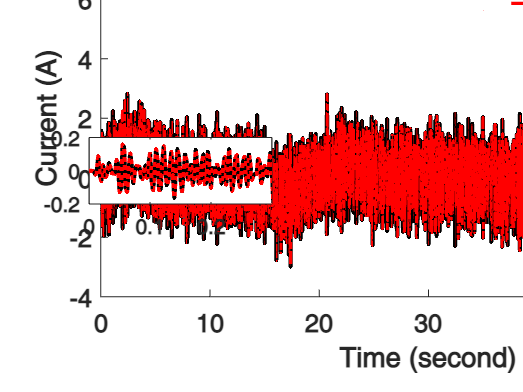

%% 电机电流
ylab1 = 'Current (A)';
ylab2 = 'Error of state estimation (A)';

choice = 1;
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.7 1.6 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice)./k_current,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)./k_current,'r-.','LineWidth',1.5);
% p2.Color(4) = 0.5;
legend([p1 p2],'actual state','estimated state','box','off');
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
ylim([-0.004,0.008])
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
box off;

a2 = axes('Position',[0.17 0.48 0.35 0.17]);
axes(a2);
p1 = plot(out.tout,out.xreal(:,choice),'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice),'r:','LineWidth',2);
xlim(a2,[0,0.3]);
a2.FontWeight = 'bold';
a2.FontSize = 10;

exportgraphics(gcf,['obser' num2str(choice) '.pdf'],'ContentType','vector');

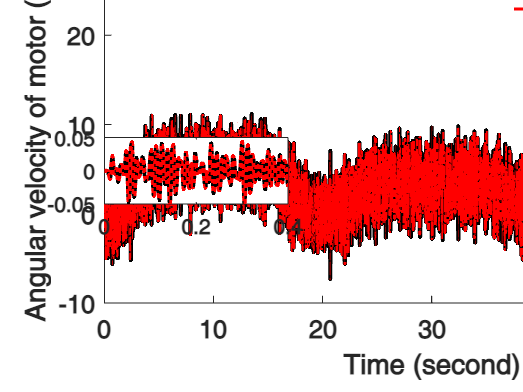

%% 电机转速

ylab1 = 'Angular velocity of motor (rad/s)';
ylab2 = 'Error of state estimation (rad/s)';

choice = 2;

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

% t.OuterPosition = [0.5 0.5 9 10];
% t.Position = [1.75 1.5 8 9];
nexttile;
p1 = plot(out.tout,out.xreal(:,choice),'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice),'r-.','LineWidth',1.5);
% p2.Color(4) = 0.5;
legend([p1 p2],'actual state','estimated state','box','off');
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
ylim([-0.1,0.3])
box off;
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
ax.YAxis.Exponent = -2;

a2 = axes('Position',[0.2 0.48 0.35 0.17]);
axes(a2);
p1 = plot(out.tout,out.xreal(:,choice),'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice),'r:','LineWidth',2);
xlim(a2,[0,0.4]);
a2.FontWeight = 'bold';
a2.FontSize = 10;

exportgraphics(gcf,['obser' num2str(choice) '.pdf'],'ContentType','vector');

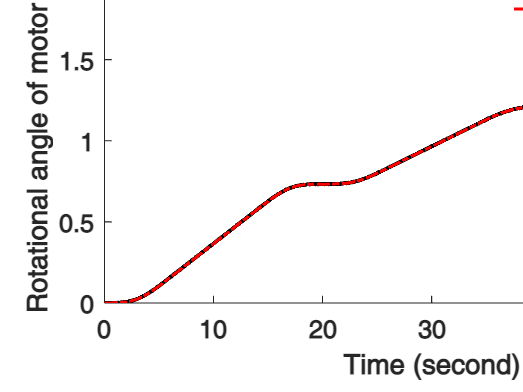



%% 电机转角

ylab1 = 'Rotational angle of motor (rad)';
ylab2 = 'Error of state estimation (rad)';

choice = 3;

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];
nexttile;
p1 = plot(out.tout,out.xreal(:,choice)*k_deg2rad,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)*k_deg2rad,'r-.','LineWidth',1.5);
legend([p1 p2],'actual state','estimated state','box','off');
ylim([0 2.2])
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
box off;
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;

exportgraphics(gcf,['obser' num2str(choice) '.pdf'],'ContentType','vector');

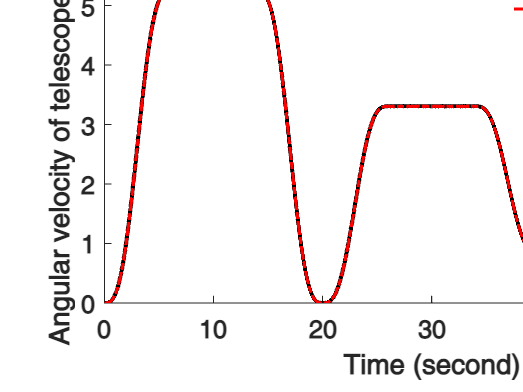


%% 望远镜转速
ylab1 = 'Angular velocity of telescope (rad/s)';
ylab2 = 'Error of state estimation (rad/s)';

choice = 4;

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice),'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice),'r-.','LineWidth',1.5);
legend([p1 p2],'actual state','estimated state','box','off');

xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
box off;
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
ax.YAxis.Exponent = -2;

exportgraphics(gcf,['obser' num2str(choice) '.pdf'],'ContentType','vector');

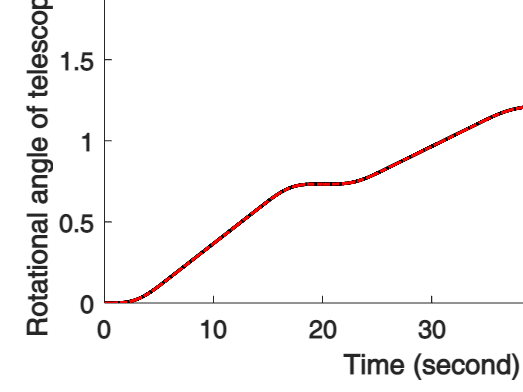


%% 望远镜转角
ylab1 = 'Rotational angle of telescope (rad)';
ylab2 = 'Error of state estimation (rad)';

choice = 5;
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice)*k_deg2rad,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)*k_deg2rad,'r-.','LineWidth',1.5);
legend([p1 p2],'real state','estimation','box','off');
ylim([0 2.2])
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
box off;

exportgraphics(gcf,['obser' num2str(choice) '.pdf'],'ContentType','vector');

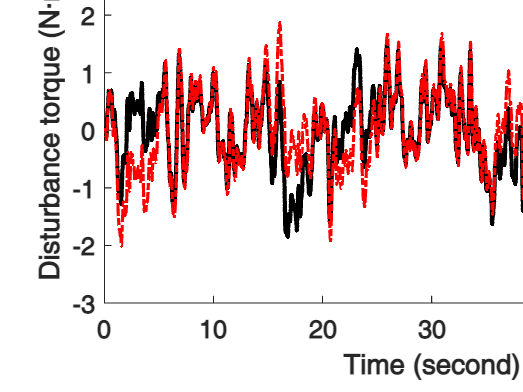


%% 扰动观测

choice = 6;
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
hold on;
p1 = plot(out.tout(1:end-1),out.dreal(1:end-1),'k','LineWidth',2);
p2 = plot(out.tout(1:end-1),out.dhat(1:end-1),'r-.','LineWidth',1.5);


legend([p1 p2],'real state','estimation','box','off');
% grid on;
xlabel('Time (second)','FontWeight','bold');
ylabel('Disturbance torque (N·m)','FontWeight','bold');
ylim([-300 320]);
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
ax.YAxis.Exponent = 2;

exportgraphics(gcf,['obser' num2str(choice) '.pdf'],'ContentType','vector');

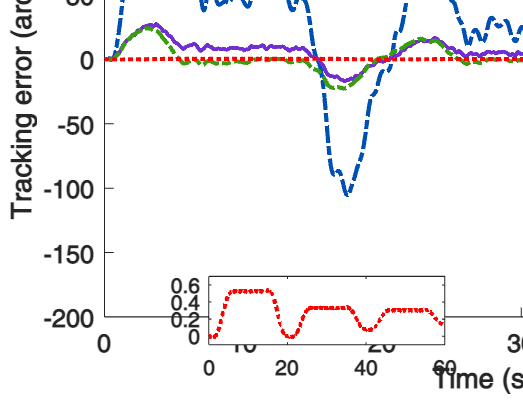

%% 跟踪误差对比图
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
% t.OuterPosition = [0.5 0.5 14 14];
t.Position = [1.75 1.5 14 8];

nexttile;
hold on;
p1 = plot(out.tout,out.PID,'k-.','LineWidth',2,'Color',[0, 80, 179]/255);
p2 = plot(out.tout,out.ADRC,'k','LineWidth',2,'Color',[114, 46, 209]/255);
p3 = plot(out.tout,out.OF,'k-.','LineWidth',2,'Color',[56, 158, 13]/255);
p4 = plot(out.tout,out.PROPOSE,'r:','LineWidth',2);

ylim([-200 170]);
xlabel('Time (second)','FontWeight','bold');
ylabel('Tracking error (arcsec)','FontWeight','bold');
legend('PID','ADRC','DOFC','Proposed Method','box','off','Orientation','horizontal','Location','northoutside');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
box off;

a2 = axes('Position',[0.4 0.15 0.45 0.17]);
axes(a2);
hold on;
% p1 = plot(out.tout,out.PID,'k-.','LineWidth',2,'Color',[0, 80, 179]/255);
% p2 = plot(out.tout,out.ADRC,'k--','LineWidth',2,'Color',[114, 46, 209]/255);
% p3 = plot(out.tout,out.OF,'k','LineWidth',2,'Color',[56, 158, 13]/255);
p4 = plot(out.tout,out.PROPOSE,'r:','LineWidth',2);
xlim(a2,[0,60]);
ylim(a2,[-0.1,0.7]);
% ylim(a2,[-25,30]);
a2.FontWeight = 'bold';
a2.FontSize = 10;
a2.Box = "on";


f = gcf;
f.Units = "centimeters";
f.OuterPosition = [2 2 18 14];

exportgraphics(gcf,'trackingerror.pdf','ContentType','vector');